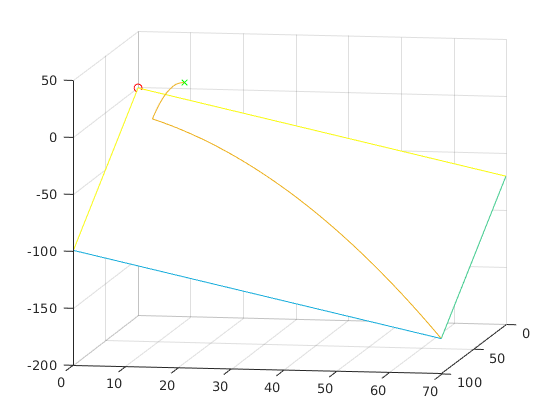

nBounces = 2;
timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [10; 10; 10];
v_0 = [2; -2; 2];
normal = [1; 1; 1]; % this value may be overwritten later
origin = [0; 0; 0];

[T, States, ~, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @(~, ~)(normal), [0, 0]);
plot_bounce(States, p_0, normal);

States(T == endTimes(1), :) % the location of the first bounce

ans =     10    10    10     2    -2     2


States(T == endTimes(2), :) % this should be very close to the origin if all the math is right

ans =     10    10    10     2    -2     2


## Stationary target:

To simulate the bouncing ball control for a stationary target, simply pass an <X, Y> position vector to mark out the desired target position. For stationary targets, an `nBounces` has to be manually determined.

timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

stationary_target = [0, 0];
nBounces = 4;
[T, States, Normals, Targets, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, stationary_target);

## Moving targets:

With moving targets, the syntax is a bit different:

- Instead of just a vector for a target position, `Targets` is now a row matrix of target X and Y positions. Note that these are desired bounce positions, matching the indices of the bounces. Since the first bounce is never accurate the first "target" position can be diregarded.

- Since we have a bunch of target bounces, we want to determine the number of bounces based on the amount of target positions. Conveniently, they should be equal to each other

%nBounces = 10;
timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [10; 10; 10];
v_0 = [2; -2; 2];
origin = [0; 0; 0];

Targets = [0, 0
            0, 0;
            1, 1;
            2, 2;
            2, 2;
            2, -2;
            -3, 3;
            0, 0;
            0, 0;];

nBounces = size(Targets, 1);

[T, States, Normals, Targets, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, Targets);

## Animation:

NOTE: The simulations run **much** faster when not in a livescript. If possible, call the below function from your command window instead.

The bounce animation function takes existing simulation data and simulates it. Note that you must first simulate the bouncing with `bounceSim` first. `bounce_animation` merely animates the states generated by `bounceSim`.

% Simulate, without saving gif:
bounce_animation(T, States, Normals, Targets, false)

% Simulate, and save gif:
bounce_animation(T, States, Normals, Targets, true)

function N = calculate_normal(States, target)
    P_t = States(1:3);
    V_t = States(4:6);
    
    func_Posf_of_N = @ (N) landing_position(N, 2, 9.8, 0.95, V_t, P_t);
    func_XofN = @ (N) (dot(func_Posf_of_N(N), [1 0 0]));
    func_YofN = @ (N) (dot(func_Posf_of_N(N), [0 1 0]));
    
    func_DistofN = @ (N) ((func_XofN(N) - target(1))^2 + (func_YofN(N) - target(2))^2);
    
    search_options = optimset('MaxFunEvals', 1000);
    N = fminsearch(func_DistofN, [0; 0; 1], search_options);
    N = N/norm(N);
end

function f = plot_bounce(States, p_0, normal)
    f = figure();
    hold on;
    
    plot3(0, 0, 0, 'ro');
    plot3(p_0(1), p_0(2), p_0(3), 'gx');
    
    plot3(States(:, 1), States(:, 2), States(:, 3));
    view(100, 10);
    
    Xbounds = [min(min(States(:, 1)), 0), max(max(States(:, 1)), 0)];
    Ybounds = [min(min(States(:, 2)), 0), max(max(States(:, 2)), 0)];
    
    [X, Y] = meshgrid(Xbounds, Ybounds);
    Z = -normal(1)/normal(3) * X - normal(2)/normal(3) * Y;
    mesh(X, Y, Z);
    
    grid on
end